# Project: Find Optimal Buying-low Selling-high Strategy for mean-reverting stock

## Yida Chen

## Simulate the Stock Price with Brownian Motion:

The stock price is $S\left(t\right)\;=e^{X\left(t\right)}$ where $X\left(t\right)$ is governed by the differential equation below:


$$\textrm{dX}\left(t\right)=\lambda \left(\mu -X\left(t\right)\right)\textrm{dt}+\sigma \;\textrm{dW}\left(t\right)$$


$\lambda$ = Speed of mean reversion

$\mu$ = Long run mean

$\sigma$ = Volatility of the process

clf;
clear;

NSample = 100;
N_T = 100;
T = 100;
t0=0;

[TProcess, BProcess] = BrownMotion(NSample, t0, 0, T, N_T);

t0=0;
y0 = [2];
h = (T - t0) / (N_T - 1);


stock_prices = [];

for k=1:NSample
    w_diff = diff(BProcess(:, k));
%     w_diff = normrnd(0, sqrt(h), N_T-1);
    x_prime = @(t, y) 0.8 * (2 - y(1)) + 0.5 * (w_diff(int32(t / h) + 1));
    f = {x_prime};
    
    [ymat, t] = EulerSystem(f, t0, y0, T, N_T);
    stock_prices = cat(2, stock_prices, exp(ymat(:, 1)));
end

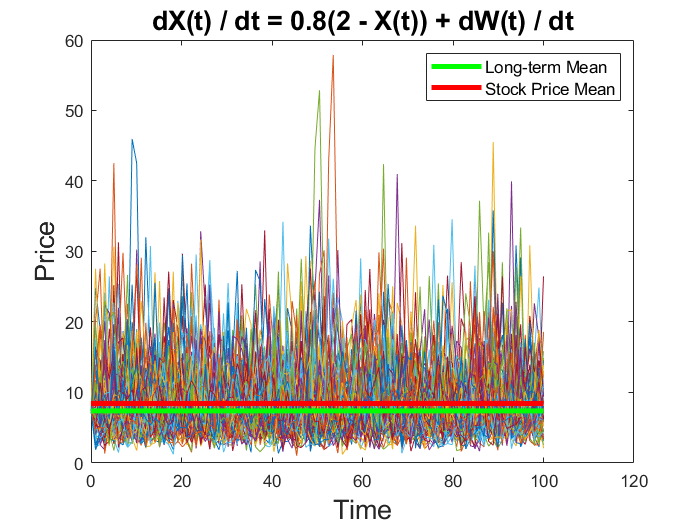

clf;
for k=1:NSample
    plot(t, stock_prices(:, k))
    hold on
end
p = [];
p(1) = plot(t, ones(length(t), 1) * exp(2),'g','LineWidth',3, 'DisplayName', "Long-term Mean");
p(2) = plot(t, ones(length(t), 1) * mean(mean(stock_prices)),'r','LineWidth',3, 'DisplayName', "Stock Price Mean");
title("dX(t) / dt = 0.8(2 - X(t)) + dW(t) / dt",'FontSize', 16)
xlabel("Time", 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
legend(p, 'FontSize', 10)
hold off

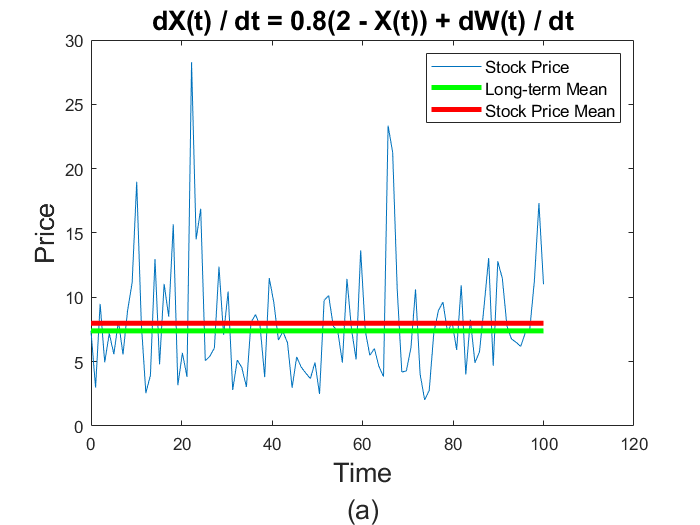

clf;
plot(t, stock_prices(:, 2))
hold on
plot(t, ones(length(t), 1) * exp(2),'g','LineWidth',3)
plot(t, ones(length(t), 1) * mean(stock_prices(:, 2)),'r','LineWidth',3)
hold off
title("dX(t) / dt = 0.8(2 - X(t)) + dW(t) / dt",'FontSize', 16)
xlabel({"Time", "(a)"}, 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
legend("Stock Price", "Long-term Mean", "Stock Price Mean",'FontSize', 10)

## Global Optimization

Calculate the reward over multiple possible trends of stock prices given the same initial conditions.

b0 = 5

b0 = 5

s0 = 18

s0 = 18

reward =     8.3068    9.0206    9.1040    9.1879    9.0944    9.2157    9.0252    9.1750    9.1128    9.2791    8.9658    9.2012    9.1598    9.2967    8.9895    9.1212    9.2475    9.2582    9.0378    9.1821    9.0965    9.2845    9.1366    9.2729    9.2280    9.2899    9.2194    9.3031    9.1141    9.2343    9.0686    9.2363    9.0758    9.2266    9.0314    9.2369    9.0798    9.2044    8.9718    9.2215    9.0605    9.1349    9.1372    9.2173    9.0876    9.2978    9.0636    9.2028    9.1512    9.1615


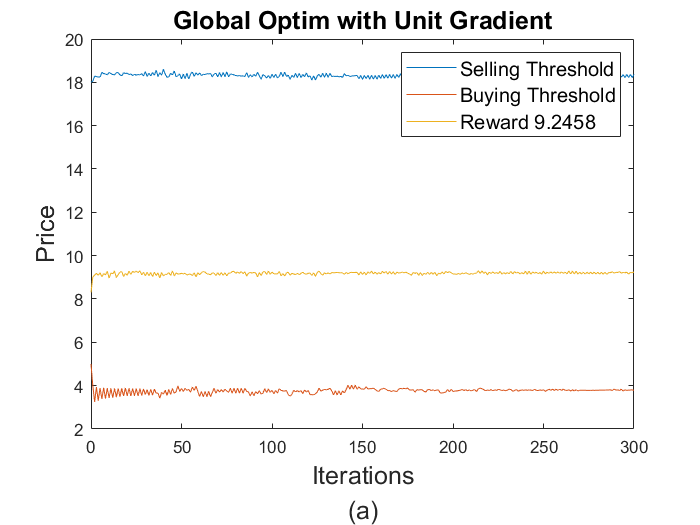

reward =     8.3068    8.8643    9.0275    8.9922    9.0321    9.0924    9.0524    9.1095    9.0484    9.1132    9.0210    9.0912    9.1621    9.0934    9.1540    9.1021    9.1518    9.1037    9.1475    9.1050    9.1039    9.0960    9.1128    9.0880    9.1208    9.0808    9.1502    9.0816    9.1452    9.0824    9.1296    9.0771    9.2347    9.0777    9.2149    9.0783    9.2144    9.0788    9.2139    9.0794    9.2134    9.0798    9.2130    9.0875    9.2126    9.0925    9.2122    9.0929    9.1939    9.0901


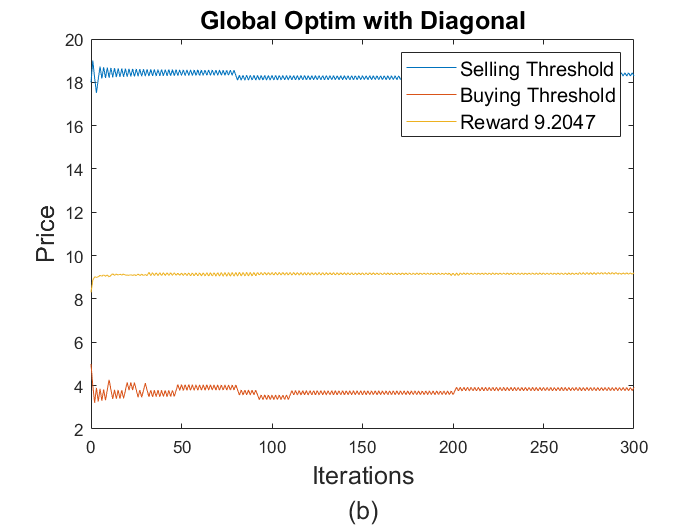

reward =     8.3068    9.0099    8.9206    9.0646    8.9647    9.1137    8.9623    9.0687    8.9435    9.0857    9.1205    9.0516    9.0532    9.0422    9.0622    9.0456    9.0564    9.0510    9.0515    9.0557    9.1149    9.0598    9.1111    9.0634    9.1100    9.0666    9.1070    9.0695    9.1043    9.0721    9.1019    9.0745    9.0996    9.0767    9.0975    9.0787    9.0956    9.1211    9.1052    9.1189    9.1119    9.1169    9.1139    9.1150    9.1158    9.1139    9.1145    9.1153    9.1615    9.1166


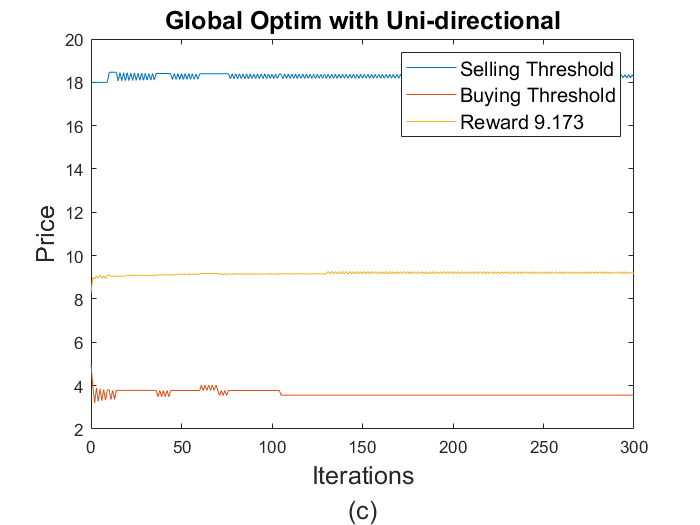

num_iter = 300;

rewards = {};
s_s = {};
b_s = {};
strategis = ["Adaptive Gradient", "Unit Gradient", "Diagonal", "Uni-directional"];
x_labels = ["0", "(a)", "(b)", "(c)"];

for mode=1:3
    s = [];
    b = [];
    reward = [];
    b(1) = b0;
    s(1) = s0;
    for iter=1:num_iter    
        c = (iter) ^ (-1/3);
        reward(iter) = TransactionReward(stock_prices, b(iter), s(iter), T);
        
        incre_b = b(iter) + c;
        reward_incre_b = TransactionReward(stock_prices, incre_b, s(iter), T);
        
        decre_b = b(iter) - c;
        reward_decre_b = TransactionReward(stock_prices, decre_b, s(iter), T);
        
        incre_s = s(iter) + c;
        reward_incre_s = TransactionReward(stock_prices, b(iter), incre_s, T);
        
        decre_s = s(iter) - c;
        reward_decre_s = TransactionReward(stock_prices, b(iter), decre_s, T);
        
        gradient_b = (reward_incre_b - reward_decre_b) / (2 * c);
        gradient_s = (reward_incre_s - reward_decre_s) / (2 * c);
        
        mag = sqrt(gradient_b ^ 2 + gradient_s ^ 2);
        
        [next_b, next_s] = update_bs(b(iter), s(iter), ...
            gradient_b, gradient_s, ...
            iter, c, mode);
        
        b(iter + 1) = next_b;
        s(iter + 1) = next_s;
        
        change = sqrt((b(iter + 1) - b(iter))^2 + (s(iter + 1)- s(iter))^2);
        if iter > 1 && change < 0.001
            break
        end
    end
    reward(iter + 1) = TransactionReward(stock_prices, b(iter + 1), s(iter + 1), T)
    
    figure()
    plot(linspace(0, length(reward) - 1, length(reward)), s)
    hold on
    plot(linspace(0, length(reward) - 1, length(reward)), b)
    plot(linspace(0, length(reward) - 1, length(reward)), reward)
    legend("Selling Threshold", "Buying Threshold", "Reward" + " " + string(reward(end)), "FontSize", 12)
    title("Global Optim with " + strategis(mode + 1), "FontSize", 15)
    hold off
    rewards{mode + 1} = reward;
    s_s{mode + 1} = s;
    b_s{mode + 1} = b;
    ylabel("Price", "FontSize", 15)
    xlabel({"Iterations", x_labels(mode + 1)}, "FontSize", 15)
end

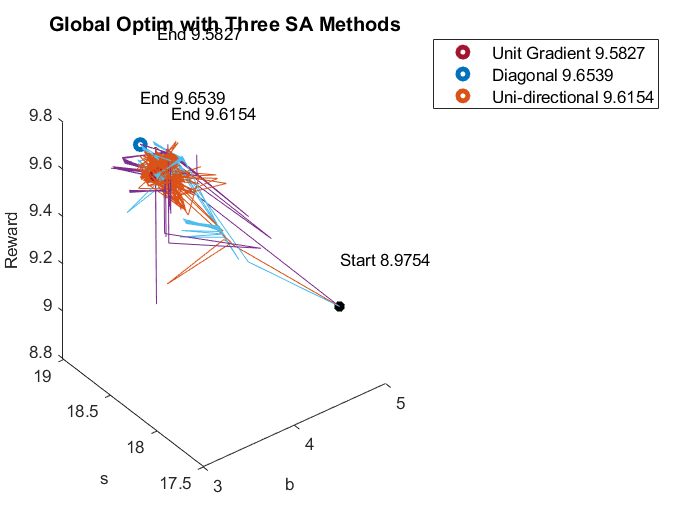

clf;
for i=2:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    plot3(b(1), s(1), reward(1), "*black", "linewidth", 3)
    hold on
    plot3(b, s, reward)
    hold on
    if i == 2
       text(b(end), s(end), reward(end) + 0.6, append('End ', string(reward(end)))) 
    else
       text(b(end), s(end), reward(end) + 0.2, append('End ', string(reward(end)))) 
    end
end
text(b_s{i}(1), s_s{i}(1), rewards{i}(1) + 0.2, append('Start ', string(rewards{i}(1))))

p = [];
for i=2:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    p(i-1) = plot3(b(end), s(end), reward(end), "o", "linewidth", 3, 'DisplayName', strategis(i) + " " + string(reward(end)));
end

xlabel("b", "FontSize", 10)
ylabel("s", "FontSize", 10)
zlabel("Reward", "FontSize", 10)
title("Global Optim with Three SA Methods", "FontSize", 12)

legend(p, "FontSize", 10)

## Before Optimizing:

What we gain by using the initial buying and selling threshold to perform one transaction on one of the stocks.

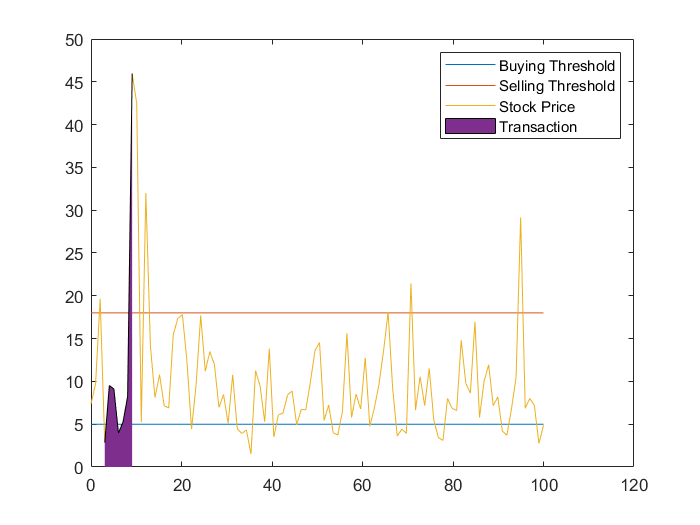

[tau_b,ColNrs] = find(stock_prices(:, 1) < b0);
[tau_s,ColNrs] = find(stock_prices(:, 1) > s0);
[tau_s,ColNrs] = min(tau_s(find(tau_s > tau_b(1))));

clf;
plot(t, ones(length(t), 1) * b0)
hold on
plot(t, ones(length(t), 1) * s0)
plot(t, stock_prices(:, 1))

one_buy_time = tau_b(1);
one_sell_time = tau_s(1);
ix = [one_buy_time: 1: one_sell_time] / (N_T - 1) * T - 1;
yz = stock_prices(one_buy_time:one_sell_time, 1);
area(ix, yz)

legend("Buying Threshold", "Selling Threshold", "Stock Price", "Transaction")

disp("Total revenue before Optimization")

Total revenue before Optimization


phi = exp(-0.01 * tau_s(1) / length(stock_prices(:, 1)) * T) * s0 * (1 - 0.01) - exp(-0.01 * tau_b(1) / length(stock_prices(:, 1)) * T) * b0 * (1 + 0.01)

phi = 11.2722

## After Optimization:

What we gain using the optimized buying and selling threshold to perform one transaction on the same stock

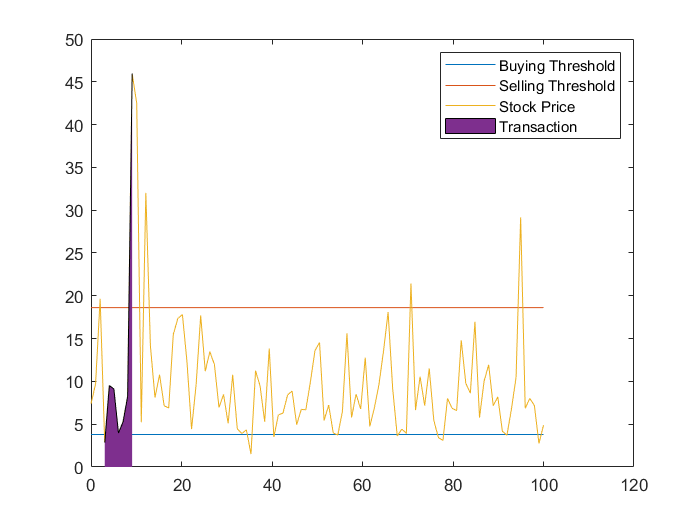

[tau_b,ColNrs] = find(stock_prices(:, 1) < b(end));
[tau_s,ColNrs] = find(stock_prices(:, 1) > s(end));
[tau_s,ColNrs] = min(tau_s(find(tau_s > tau_b(1))));

clf;
plot(t, ones(length(t), 1) * b(end))
hold on
plot(t, ones(length(t), 1) * s(end))
plot(t, stock_prices(:, 1))

one_buy_time = tau_b(1);
one_sell_time = tau_s(1);
ix = [one_buy_time: 1: one_sell_time] / (N_T - 1) * T - 1;
yz = stock_prices(one_buy_time:one_sell_time, 1);
area(ix, yz)

legend("Buying Threshold", "Selling Threshold", "Stock Price", "Transaction")

disp("Total revenue after Optimization");

Total revenue after Optimization


phi = exp(-0.01 * tau_s(1) / length(stock_prices(:, 1)) * T) * s(end) * (1 - 0.01) - exp(-0.01 * tau_b(1) / length(stock_prices(:, 1)) * T) * b(end) * (1 + 0.01)

phi = 13.0057

## Following what I have thought (Local Optimization):

Use only one OU functions, but buy and sell multiple times in one period.

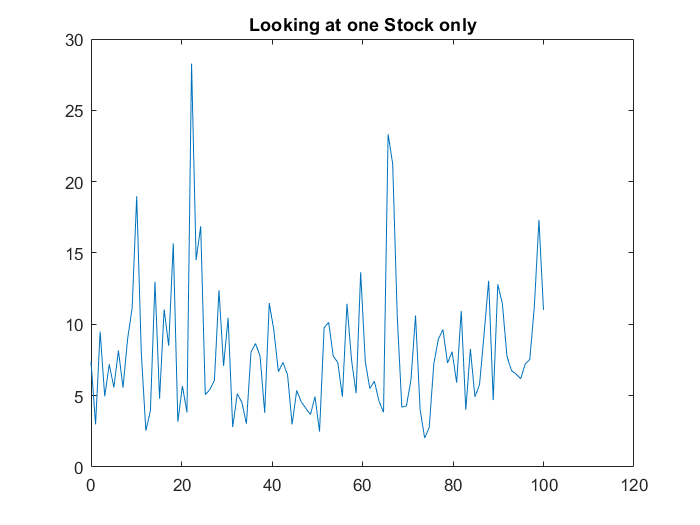

b0 = 5;
s0 = 18;
num_iter = 300;

% stock_price = stock_prices(:, randi(NSample));
stock_price = stock_prices(:, 2);

clf;
plot(t, stock_price)
title("Looking at one Stock only")
hold off

reward =    26.3979   29.5021   31.7462   32.7442   31.6508   32.0182   31.0873   32.5758   33.9701   32.7603   32.5756   31.8141   32.9508   32.6975   32.0043   33.0226   34.0085   33.1084   34.0379   33.1856   32.8884   33.7490   33.1730   33.9953   33.2353   32.9363   33.7098   33.1833   33.9286   33.6282   33.1259   33.8342   33.5389   33.0579   33.7342   33.4442   32.9818   33.6301   34.2699   33.6713   33.3899   34.0058   33.5742   34.1756   33.6117   34.1996   33.6481   33.3780   33.9472   33.5452


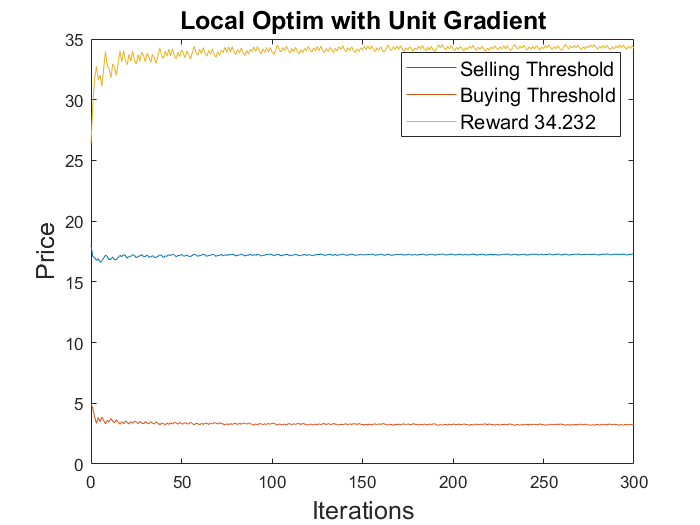

reward =    26.3979   31.1736   31.6983   31.4369   31.6633   31.4608   33.7302   31.6291   33.5945   31.7415   33.4994   31.8233   33.4280   33.5536   33.4326   33.5495   33.4363   33.5461   33.4394   33.5433   33.4420   33.5408   33.4443   33.5387   33.4463   33.5368   33.4480   34.5178   33.4673   34.4995   33.4847   34.4830   33.5004   34.4680   33.5147   34.4543   33.5279   34.4417   33.5400   34.4301   33.5512   34.4193   33.5616   34.4093   33.5713   34.3999   33.5803   34.3911   33.5888   34.3829


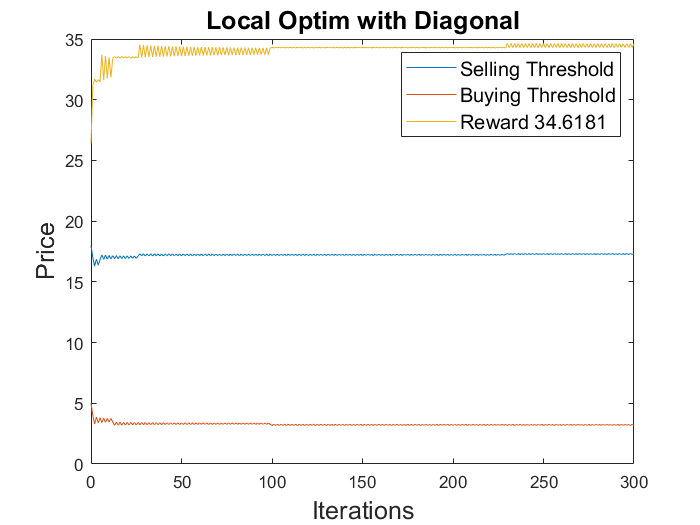

reward =    26.3979   27.9587   30.1733   32.2332   33.7360   32.3918   33.6189   32.4828   31.5802   32.5821   31.6316   32.5379   31.6702   32.5039   31.7005   32.4766   31.7252   32.4542   31.7457   32.4353   31.7632   32.4191   31.7783   32.4050   31.7915   32.3926   31.8031   32.3816   32.9496   32.3915   32.9402   32.4004   32.9317   32.4085   32.9240   32.4159   32.9169   32.4227   32.9103   32.4290   32.9043   32.4349   32.8987   32.4403   32.8934   32.4454   32.8885   32.4501   32.8839   32.4545


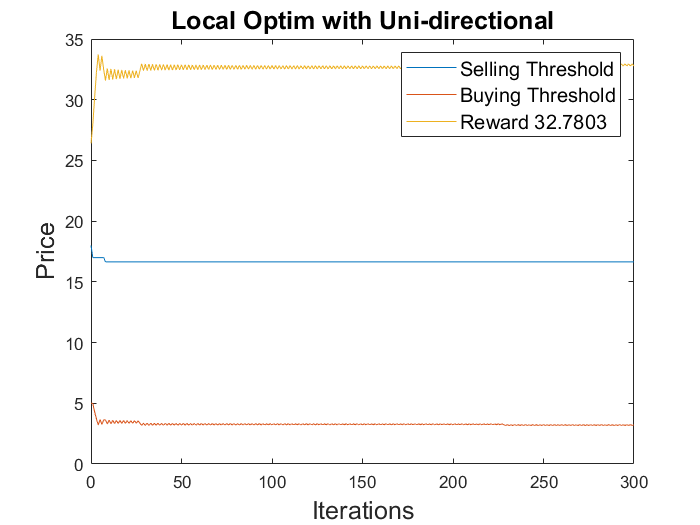


rewards = {};
s_s = {};
b_s = {};
strategis = ["Adaptive Gradient", "Unit Gradient", "Diagonal", "Uni-directional"];

for mode=1:3
    s = [];
    b = [];
    reward = [];
    b(1) = b0;
    s(1) = s0;
    for iter=1:num_iter
        c = (iter) ^ (-1/2);
        reward(iter) = MultiTransactionReward(stock_price, b(iter), s(iter), T);
        
        incre_b = b(iter) + c;
        reward_incre_b = MultiTransactionReward(stock_price, incre_b, s(iter), T);
        
        decre_b = b(iter) - c;
        reward_decre_b = MultiTransactionReward(stock_price, decre_b, s(iter), T);
        
        incre_s = s(iter) + c;
        reward_incre_s = MultiTransactionReward(stock_price, b(iter), incre_s, T);
        
        decre_s = s(iter) - c;
        reward_decre_s = MultiTransactionReward(stock_price, b(iter), decre_s, T);
        
        gradient_b = (reward_incre_b - reward_decre_b) / (2 * c);
        gradient_s = (reward_incre_s - reward_decre_s) / (2 * c);
        
        mag = sqrt(gradient_b ^ 2 + gradient_s ^ 2);
        
        [next_b, next_s] = update_bs(b(iter), s(iter), ...
            gradient_b, gradient_s, ...
            iter, c, mode);
        
        b(iter + 1) = next_b;
        s(iter + 1) = next_s;
        
        change = sqrt((b(iter + 1) - b(iter))^2 + (s(iter + 1)- s(iter))^2);
        if iter > 1 && change < 0.001
            break
        end
    end
    
    reward(iter + 1) = MultiTransactionReward(stock_price, b(iter + 1), s(iter + 1), T)
    
    figure()
    plot(linspace(0, length(reward) - 1, length(reward)), s)
    hold on
    plot(linspace(0, length(reward) - 1, length(reward)), b)
    plot(linspace(0, length(reward) - 1, length(reward)), reward)
    legend("Selling Threshold", "Buying Threshold", "Reward" + " " + string(reward(end)), "FontSize", 12)
    title("Local Optim with " + strategis(mode + 1), "FontSize", 15)
    hold off
    rewards{mode + 1} = reward;
    s_s{mode + 1} = s;
    b_s{mode + 1} = b;
    ylabel("Price", "FontSize", 15)
    xlabel("Iterations", "FontSize", 15) 
end

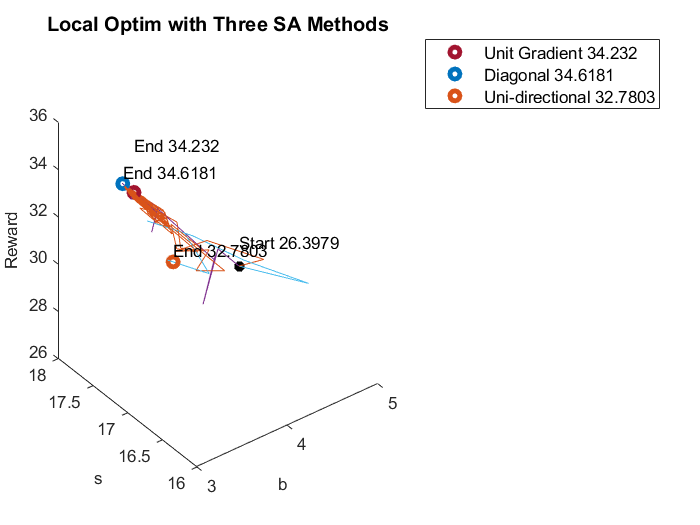

clf;
for i=2:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    plot3(b(1), s(1), reward(1), "*black", "linewidth", 3)
    hold on
    plot3(b, s, reward)
    hold on
    if i == 2
       text(b(end), s(end), reward(end) + 2, append('End ', string(reward(end)))) 
    else
       text(b(end), s(end), reward(end) + 0.5, append('End ', string(reward(end)))) 
    end
end
text(b_s{i}(1), s_s{i}(1), rewards{i}(1) + 1, append('Start ', string(rewards{i}(1))))

p = [];
for i=2:4
    b = b_s{i};
    s = s_s{i};
    reward = rewards{i};
    p(i-1) = plot3(b(end), s(end), reward(end), "o", "linewidth", 3, 'DisplayName', strategis(i) + " " + string(reward(end)));
end

xlabel("b", "FontSize", 10)
ylabel("s", "FontSize", 10)
zlabel("Reward", "FontSize", 10)
title("Local Optim with Three SA Methods", "FontSize", 12)

legend(p, "FontSize", 10)

b(end), s(end), reward(end)

ans = 3.2332

ans = 16.6464

ans = 32.7803

## Using the inital Buying and Selling Thresholds:

Much less gross income from all transactions.

one_stock_price = stock_price;
% All this part is about finding the all possible sets of 
% buying and selling times for this given stock using the
% b0 and s0

[buy_times, sell_times] = find_set_of_selling_buying_time(one_stock_price, b0, s0); 

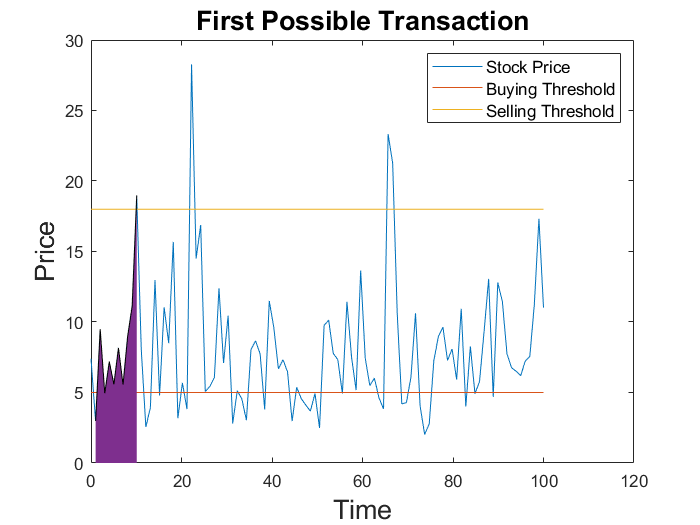

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, one_stock_price)
hold on
plot(t, ones(length(t), 1) * b0)
plot(t, ones(length(t), 1) * s0)


for i=1:1
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / (N_T - 1) * T - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

legend("Stock Price", "Buying Threshold", "Selling Threshold", "FontSize", 10)
title("First Possible Transaction", "FontSize", 16)
xlabel("Time", 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
hold off

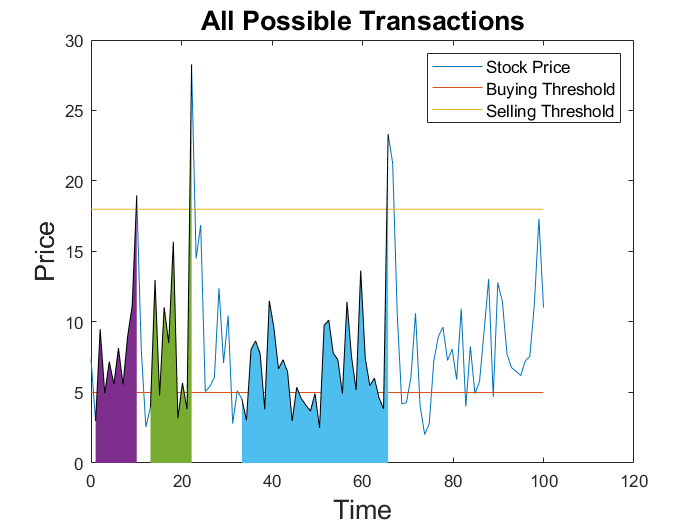

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, one_stock_price)
hold on
plot(t, ones(length(t), 1) * b0)
plot(t, ones(length(t), 1) * s0)


for i=1:length(buy_times)
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / (N_T - 1) * T - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

legend("Stock Price", "Buying Threshold", "Selling Threshold", "FontSize", 10)
title("All Possible Transactions", "FontSize", 16)
xlabel("Time", 'FontSize', 16)
ylabel("Price", 'FontSize', 16)
hold off

## Compute Revenue using the initial Threshold

% Compute the sum of gains from all possible transaction
% on this particular stock
tau_b = buy_times;
tau_s = sell_times;

phi = exp(-0.01 * tau_s / length(one_stock_price) * T) * s0 * (1 - 0.01) - exp(-0.01 * tau_b / length(one_stock_price) * T) * b0 * (1 + 0.01)

phi =    11.0138    9.7683    5.6159


disp("Total revenue before Optimization")

Total revenue before Optimization


phi = sum(phi)

phi = 26.3979

## Using the optimized Buying and Selling Thresholds:

We get a better sum of revenues from all transactions we made.

one_stock_price = stock_price;
% All this part is about finding the all possible sets of 
% buying and selling times for this given stock using the
% b and s

[buy_times, sell_times] = find_set_of_selling_buying_time(one_stock_price, b(end), s(end)); 

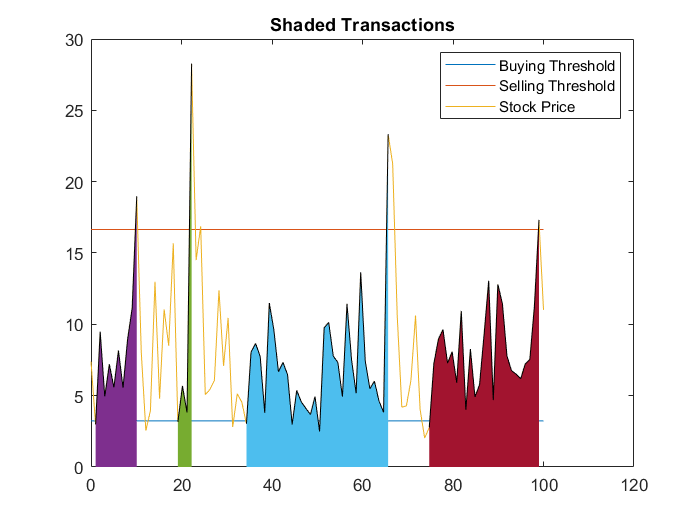

clf;
% Plot the stock price, buying & selling threshold, and 
% the transactions (shaded period)
plot(t, ones(length(t), 1) * b(end))
hold on
plot(t, ones(length(t), 1) * s(end))
plot(t, one_stock_price)

for i=1:length(buy_times)
    one_buy_time = buy_times(i);
    one_sell_time = sell_times(i);
    ix = [one_buy_time: 1: one_sell_time] / (N_T - 1) * T - 1;
    yz = one_stock_price(one_buy_time:one_sell_time);
    area(ix, yz)
end

legend("Buying Threshold", "Selling Threshold", "Stock Price")
title("Shaded Transactions")
hold off

## Compute Revenue using the Optimized Threshold

% Compute the sum of gains from all possible transaction
% on this particular stock
tau_b = buy_times;
tau_s = sell_times;

phi = exp(-0.01 * tau_s / length(one_stock_price) * T) * s(end) * (1 - 0.01) - exp(-0.01 * tau_b / length(one_stock_price) * T) * b(end) * (1 + 0.01)

phi =    11.5624   10.4203    6.2165    4.5810


disp("Total revenue after Optimization")

Total revenue after Optimization


phi = sum(phi)

phi = 32.7803

## Explore the reward function on all possible '`b'` and 's':

% Explore the surface of the reward function at all possible b and s
% b and s are the x and y axes of the plot
% and the surface (z) is the reward computed at a given (b, s)
s_all = linspace(3, 23, 50);
b_all = linspace(3, 23, 50);
reward_all = [];
for i=1:length(s_all)
    for j=1:length(b_all)
        reward_all(j, i) = MultiTransactionReward(stock_price, b_all(i), s_all(j), T);
    end
end

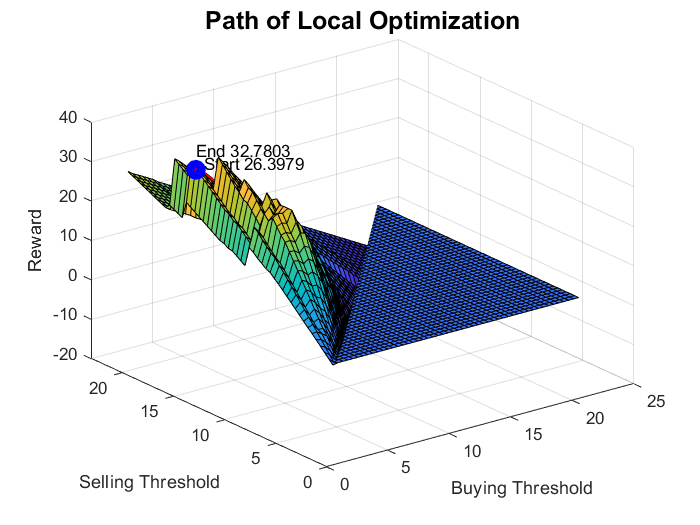

clf;
surf(b_all, s_all, reward_all)
xlabel("Buying Threshold")
ylabel("Selling Threshold")
zlabel("Reward")
%zlim([-50, 50])
hold on

plot3(b(1), s(1), reward(1), 'ogreen','linewidth',3)
plot3(b, s, reward, 'red','linewidth',2)
plot3(b(end), s(end), reward(end), 'oblue','linewidth',6)
text(b(1), s(1), reward(1) + 5, append('Start ', string(reward(1))))
text(b(end), s(end), reward(end) + 5, append('End ', string(reward(end))))
title("Path of Local Optimization", "FontSize", 15)
hold off

## Interactive Plot:

that shows how our algorithm are finding the local maximum of that reward function

s_all = linspace(3, 23, 500);
b_all = linspace(3, 23, 500);
reward_all = [];
for i=1:length(s_all)
    for j=1:length(b_all)
        reward_all(j, i) = MultiTransactionReward(stock_price, b_all(i), s_all(j), T);
    end
end

Interactive plot. Go to the next optimal point by pressing the key "k" on the keyboard.

clf;
h = surf(b_all, s_all, reward_all);
set(h,'LineStyle','none')
xlabel("Buying Threshold")
ylabel("Selling Threshold")
zlabel("Reward")
hold on

plot3(b(1), s(1), reward(1), 'ogreen','linewidth',3)
step = 5;
for i=1:step:length(s)-1
    key_press = waitforbuttonpress;
    val = get(gcf, "CurrentCharacter");
    while val ~= "k"
        key_press = waitforbuttonpress;
        val = get(gcf, "CurrentCharacter");
    end
    if i ~= 1
        delete(h);
    end
    plot3(b(i:i+ step -1), s(i:i+ step -1), reward(i:i+ step -1), 'red','linewidth',2)
    h = plot3(b(i+step -1), s(i+ step -1), reward(i+ step -1), 'oblue','linewidth',3);
    hold on
end

Error using waitforbuttonpress
waitforbuttonpress exit because target figure has been deleted

delete(h)
plot3(b(end), s(end), reward(end), 'oblue','linewidth',6)
hold off

key_press = waitforbuttonpress
val = get(gcf, "CurrentCharacter")

# Function Definitions:

function [ymat, t]=EulerSystem(f, t0, y0, b, N)
    ymat = zeros(N, length(y0));
    h = (b - t0) / (N - 1);
    for i=1:length(y0)
        ymat(1, i) = y0(i);
    end
    t(1) = t0;
    for j=2:N
        for i=1:length(y0)
            ymat(j, i) = ymat(j - 1,i) + h * f{i}(t(j-1), ymat(j - 1, :));
            t(j) = t(j - 1) + h;
        end
    end
end

function [ymat, t]=RKSystem(f, t0, y0, b, N)
    ymat = zeros(N, length(y0));
    h = (b - t0) / N;
    for i=1:length(y0)
        ymat(1, i) = y0(i);
    end
    t(1) = t0;
    for j=2:N + 1
        for i=1:length(y0)
            k1 = h * f{i}(t(j-1), ymat(j - 1, :));
            k2 = h * f{i}(t(j-1) + h, ymat(j - 1, :) + k1);
            ymat(j, i) = ymat(j - 1,i) + (1 / 2) * (k1 + k2);
            t(j) = t(j - 1) + h;
        end
    end
end

function [TProcess, BProcess]=BrownMotion(sample, t0, y0, b, N)
    BProcess = [];
    TProcess = [];
    NSample = sample;
    N_T = N;
    T = b;
    
    for k = 1:NSample
        B = y0;
        t = t0;
        BProcess(1,k)=B; TProcess(1,k)=t;
        for i=2:N_T
            dt =  T/N_T;
            t = t + dt;
            B = B + sqrt(dt)*randn(1); %increments in B are normally distibuted with variance dt
            BProcess(i,k) = B;
            TProcess(i,k) = t;
        end
    end
end


function [next_b, next_s] = update_bs(b, s, gradient_b, gradient_s, ...
    iter, c, mode)
    eps =0.000001;
    % Update strategy 0 gradient vector
    if mode == 0
        next_b = b + gradient_b / iter;
        next_s = s + gradient_s / iter;
    % Update strategy 1 unit vector
    elseif mode == 1
        mag = sqrt(gradient_b ^ 2 + gradient_s ^ 2);
        
        next_b = b + gradient_b / (mag + eps) * c;
        next_s = s + gradient_s / (mag + eps) * c;
    % Update strategy 2 move in diagonal 
    elseif mode == 2
        if gradient_b > 0
            next_b = b + c;
        else
            next_b = b - c;
        end
        
        if gradient_s > 0
            next_s = s + c;
        else
            next_s = s - c;
        end
    % Update strategy 3 move in largest gradient (eithr b or s)
    elseif mode == 3
        if abs(gradient_s) > abs(gradient_b)
            next_b = b;
            if gradient_s > 0
                next_s = s + c;
            else
                next_s = s - c;
            end
        else
            next_s = s;
            if gradient_b > 0
                next_b = b + c;
            else
                next_b = b - c;
            end
        end
    end
end


% Global Optimization
% Optimize on one transaction of multiple different stock prices
function reward=TransactionReward(stock_prices, b, s, T)
    if b > s
        reward = 0;
        return
    end
    phi = [];
    for k=1:length(stock_prices(1, :))
        [tau_b,ColNrs] = find(stock_prices(:, k) < b);
        [tau_s,ColNrs] = find(stock_prices(:, k) > s);
        if length(tau_b) < 1
            continue
        end
        [tau_s,ColNrs] = min(tau_s(find(tau_s > tau_b(1))));
        if length(tau_s) < 1
            continue
        end
        tau_b = tau_b(1);
        phi(k) = exp(-0.01 * tau_s / length(stock_prices) * T) * s * (1 - 0.01) - exp(-0.01 * tau_b / length(stock_prices) * T) * b * (1 + 0.01);
    end
    
    if length(phi) < 1
        reward = 0;
    else
        reward = sum(phi) / length(stock_prices(1, :));
    end       
end


% Local Optimization
% Optimize on multiple transaction of one randomly chosen stock
function reward=MultiTransactionReward(one_stock_price, b, s, T)
    if b > s
        reward = 0;
        return
    end
    [tau_b,ColNrs] = find(one_stock_price < b);
    [tau_s,ColNrs] = find(one_stock_price > s);
    
    buy_times = [];
    sell_times = [];
    
    nth_set = 1;
    prev_s = 1;
    i = 1;
    while i <= length(tau_b)
        b_time = tau_b(i);
        s_time = 0;
        RowNrs = [];
        for j=prev_s:length(tau_s)
            if tau_s(j) > tau_b(i)
                s_time = tau_s(j);
                buy_times(nth_set) = b_time;
                sell_times(nth_set) = s_time;
                nth_set = nth_set + 1;
                prev_s = j + 1;
                
                [RowNrs,ColNrs] = find(tau_b > sell_times(end));
                if length(RowNrs) < 1 
                    break
                end
                if prev_s > length(tau_s)
                    break
                end
                i = RowNrs(1);
                break
            end
        end
        if length(RowNrs) < 1 
            break
        end
        if prev_s > length(tau_s)
            break
        end
        i = i + 1;
    end
    
    tau_b = buy_times;
    tau_s = sell_times;
    
    if length(tau_b) < 1
        reward = 0;
    else
        phi = exp(-0.01 * tau_s / length(one_stock_price) * T) * s * (1 - 0.01) - exp(-0.01 * tau_b / length(one_stock_price) * T) * b * (1 + 0.01);
        reward = sum(phi);
    end
end


function [buy_times, sell_times]=find_set_of_selling_buying_time(one_stock_price, b, s)
    [tau_b,ColNrs] = find(one_stock_price < b);
    [tau_s,ColNrs] = find(one_stock_price > s);
    
    buy_times = [];
    sell_times = [];
    
    nth_set = 1;
    prev_s = 1;
    i = 1;
    while i <= length(tau_b)
        b_time = tau_b(i);
        s_time = 0;
        
        for j=prev_s:length(tau_s)
            if tau_s(j) > tau_b(i)
                s_time = tau_s(j);
                buy_times(nth_set) = b_time;
                sell_times(nth_set) = s_time;
                nth_set = nth_set + 1;
                prev_s = j + 1;
                
                [RowNrs,ColNrs] = find(tau_b > sell_times(end));
                if length(RowNrs) < 1 
                    return
                end
                if prev_s > length(tau_s)
                    return
                end
                i = RowNrs(1);
                break
            end
        end
        i = i + 1;
    end
end